% Author: Daniel Surinach
% Modified: Ibrahim Oladepo | 30 March 2023

clear;
clc;
close all

### This funcion gets XY  manual coordinates from a behavior video using drawpoint

% User input

% Iinitalize behavioral arena type
% OpenField | BarnesMaze | APA
behavior = 'APA'

% Folder where behavior video is
input_folder = 'H:\Other computers\My PC\PhD_UOM\General\BSBRL\Projects\Motorized_Commutator\Python\Videos';

% Folder to save output frames and data
output_folder = 'H:\Other computers\My PC\PhD_UOM\General\BSBRL\Projects\Motorized_Commutator\SLEAP\Data\Ground_Truth';

% Open behavior video stream 
[vfile,vfolder] = uigetfile(fullfile(input_folder, '*.avi;*.mp4'), 'Select behavior video');

% Open video stream
vbeh = VideoReader(fullfile(vfolder, vfile));

% Get number of frames
numFrames = round(vbeh.FrameRate*vbeh.Duration);

% Select which frames to load from video. Can be random or pre-picked
framesToInspect = 50;
framelist = sort(randperm(numFrames, framesToInspect));% list of random number frames to open

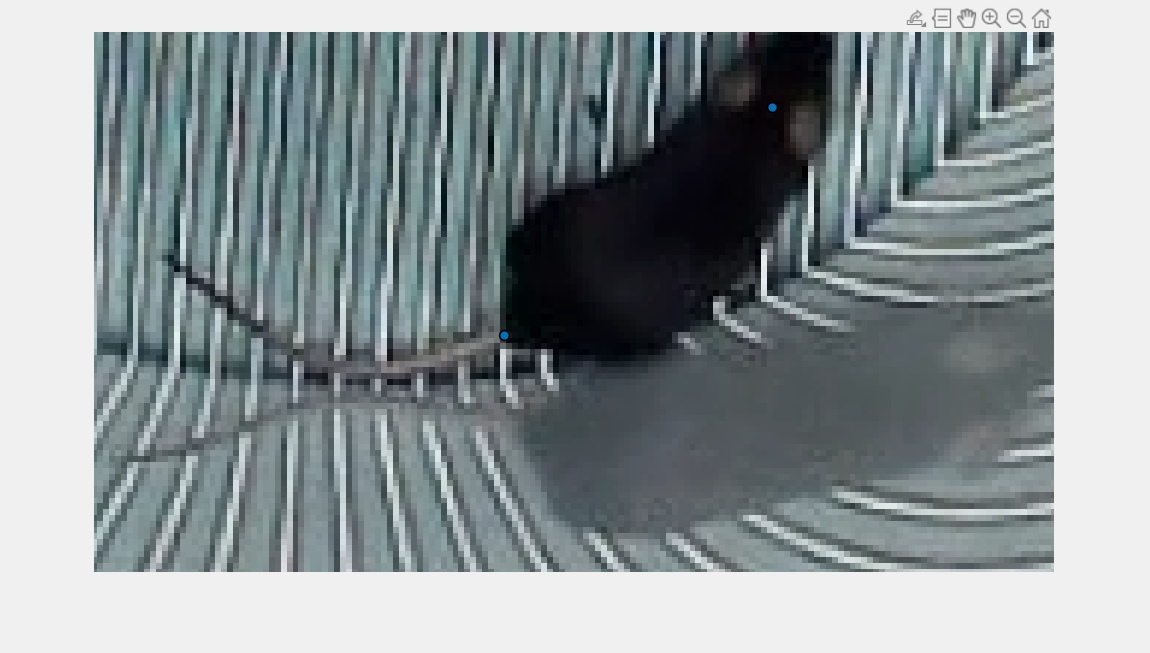

% Open video frames and manually annotate
numlabels = 2;
count = 1;
figure
x = [];
y = [];

for i = 1:length(framelist)
    
    % Read and display frame
    im = read(vbeh, framelist(i));       
    imshow(im)
    
    for j = 1:numlabels
        
        % Draw point with cursor; Can zoom on image
        point = drawpoint;

        % Store xy coordinates of the drawn point
        x(count,j) = point.Position(1); 
        y(count,j) = point.Position(2);
    
    end
    
    % Save image of labeled points
    figure('visible', 'off') 
    imshow(im)
    hold on
    
    for j = 1:numlabels
        plot(x(count, j), y(count, j),'*')
    end
    
    saveas(gcf, fullfile(output_folder, strcat('behaviorvideo_label_frame', num2str(framelist(i)),'.jpeg')))
    close
    count = count+1;
    
end

% Concatenate data into a matrix
outData = [x(:,1) y(:,1) x(:,2) y(:,2) framelist'];

% Format file name for the data to save to disk
FILENAME = append(behavior, '_Ground_Truth.csv');
FILENAME = append('\', FILENAME);
FILENAME = append(output_folder, FILENAME);

% Save data to disk
writematrix(outData, FILENAME)